# `Longitudinal Vehicle Model`

# `For Precise Vehicular Braking`

` Equations of motion on a wheel Free body diagram`

`Simulink & Matlab`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`updated 5/12/2023 independantly, taking inspiration from a Tesla interview assessment`

`prior project from Autonomy in Vehicles ECE 5553  | Ohio State University | `

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

# `Contents `

`1. Introduction`

`2. Powertrain model`

`    a) Model Selection`

`    b) drive torque derivation`

`3. Wheel Free Body Diagram`

`    a) Equations of Motion`

`    b) Component Equations`

`4. Simulink model`

`    a) Top level diagram`

`    b) Sub Components, corresponding to the EOM's`

`5. Simulations`

`    a) LTI approximation of an acceleration simulation `

`    c) 20 Pure acceleration simulations `

`        i) velocity time graph`

`    d) 20 Coast down simulations`

`        i) velocity time graph`

`        ii) second order polynomial approximation`

`    e) 20 brake simulations`

`        i) velocity time graph`

`    f) 400 brake simulations `

`6. Summarizing the Data`

`    a) Average Accelerations`

`        i) dependance on starting velocity`

`        ii) dependance on net wheel torque`

`    b) Reversing the simulation`

`        i) the regression problem`

`7. Conclusions and future work`

`8. Functions`

# `Introduction`

`    Inspired through study at Ohio State in 2023, written by Brian Lesko, receiving a MS Summer 2023 in Mechanical Engineering. Bachelors of Mechanical engineering received spring of 2022. `

`    This investigation explores accelleration and decceleration of a generic vehicle. The powertrain model exists to estimate the longitudinal state of a vehicle. In the coming sections, the overall model will be selected, which will limimit the accuracy of the results. Next, this model will be disected into its component free body diagrams so that the equations describing its motion can be written. Then, the equations of motion (EOM) will be utilized to create a simulink diagram to numerically simulate vehicle movement under different conditions. Afterwards, the system will be approximated with a linear time invariant equation or LTI system equation. This equation will make further vehicle dynamics problems easier to solve. The simplified equation will then be used as the basis for designing a control system to acheive precice vehicle braking. `

# `Powertrain Model`

`The following models were evaluated during the model consideration process. The selection criterion consisted of balancing complexity with perceived significance of results.`

`The Flexible driveshaft model`

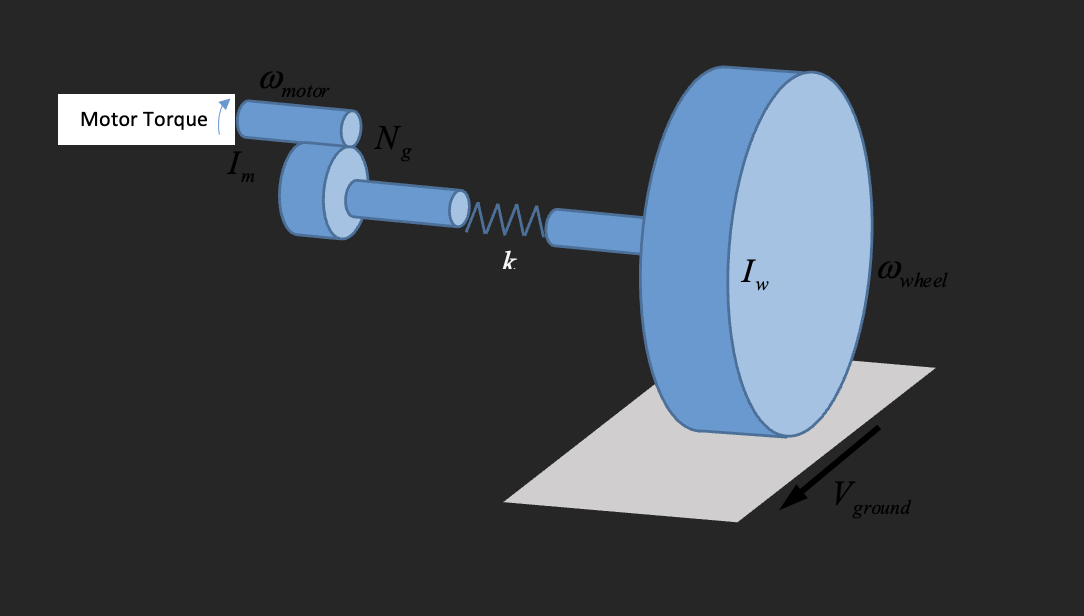

`The clockwise spinning motor is connected to a gear, flexible driveshaft, and wheel in series. `

`    This model is predicted to produce increased vibration in the vehicle state, positon, speed, or acceleration. The analysis is more complex but masy increase accuracy of results. Therefor, because the model is more complex with a relatiely small amount of accuracy to gain, this model is left for analysis at a later date. `

`The selected model consists of the same elements as the previous, but lacking a flexible driveshaft. A motor, gear, then wheel.`

`Diagram []`

`The independant bodies to analyze in this model consist of the wheel, the motor, and the gear.`

# `Wheel Free Body Diagram`

`The wheel's free body diagram is prediced to be the primary importance because of the road tire interaction dominating the vehicle chararacteristics. Below is the free body diagram of the wheel on a sloped road.`

`Wheel Free Body Diagram, for Longitudinal Performance`

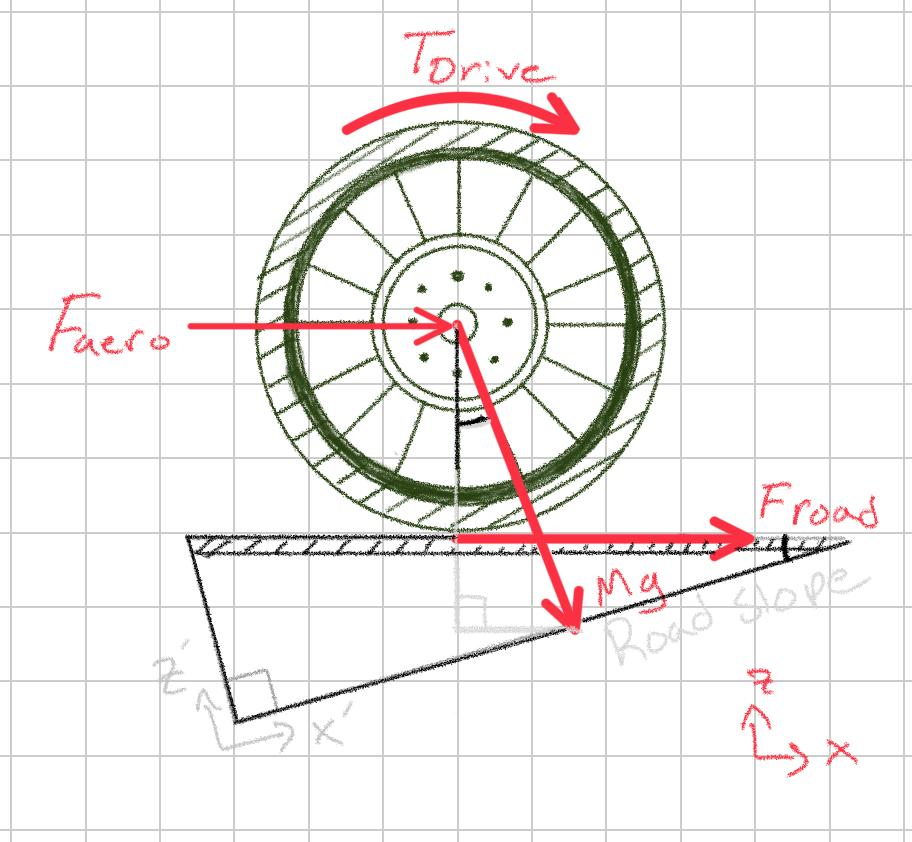

`MODIFY   [Tbrake needs added]`

`Brian Lesko`

`The interaction from the gear and motor is transmitted through the torque Tdrive. The vehicle's road interaction is characterized by the road force, The vehicle's weight is split into two forces due to the road slope. The vehicle's interaction with the air is approximated with a force through the center of the tire. Particularly, the air force on the vehicle is an approximation that may introduce some model innacuracy, as the true aerodynamic force acts on the entire vehicle's profile and likely sums to a different point. Furthermore, the single wheel approximation implies that any pitch dynamics of the vehicle are ignored, such as the back wheel having more traction during acceleration and the front wheel having more traction during braking. A more complex analysis is left for another time becuase these results are hypothesized to fit the desired accuracy. `

## `Wheel Equations of Motion`

`The equations of motion of a system are derived after creating the relevant free body diagrams. On each body, the forces and torques are summed for use with Newtons Second Law, F=ma or T=Ia.`

`The wheel's equations of motion are as follows: `

`The Sum of forces in the X yeilds: `

`M x'' = Fr + Fgr - Faero - Frr`

`where Fgr and Frr are the components of the vehicle's weight force.`

`Sum of moments (clockwise positive)`

`Iw theta''  = Tdrive - Tbrake - (Rw * Froad) - Fgr`

`where Rw is the wheel radius`

## `Component Equations`

`Driveshaft Torque (Td, Tdrive):     Td = Tmotor * Ng `

`Road Force (Fr, Froad):       Fr = Cx * slip`

`slip:             slip   = (theta' * Rw - x') / MAX(x' , theta' * Rw , 1e-7)`

`Drag Force (Fa,Faero):  Fa = (x' + wind force)^2 * air density * Cd * Vehicle Frontal Area * 1 / 2 wheels`

`Vertical Load Components `

`    Rolling Resistance      Frr = cos(road slope) * Crr * M*g`

`    Grade           Fgr = sin(road slope) * M*g`

## `Variables `

`Text variables, CSV format`

`Variable,Description,Units`

`k,Driveshaft stiffness constant,Nm/rad`

`Ng,Gear ratio constant (motor speed/wheel speed),None`

`Tmotor,Input,Nm`

`theta_shaft,Shaft state derived from the motor FBD,rad`

`theta,Wheel state,rad`

`Cx,Slip Stiffness,N per slip`

`slip,Fraction of wheel slip,None`

`theta',Wheel state derivative,rad/s`

`Rw,Wheel radius,m`

`x',Wheel state derivative,m/s`

`wind force,Wind force,N`

`air density,Air density,kg/m^3`

`Cd,Drag coefficient,None`

`Vehicle Frontal Area,Vehicle Frontal Area,m^2`

`road slope,Road slope,rad`

`Crr,Rolling resistance coefficient,None`

`M,Vehicle mass,kg`

`g,Gravity,m/s^2`

`Tb - Brake Torque (Nm)`

`Iw - moment of inertia of the wheel `

# `Simulink Model `

`Simulink is a MATLAB-based graphical programming environment for modeling, simulating and analyzing multi-domain dynamic systems. It's useful because it lets engineers design, simulate, and test control systems in a virtual environment before implementing in hardware, decreasing error margin and testing time. It calculates functions, integrals, or differential equations. Blocks represent mathematical or logical functions or physical devices to relate inputs and outputs. Simulink solves these block diagram models as sets of algebraic and differential equations by numeric integration.`

`The powertrain's equations of motion were directly translated into simulink blocks, which together represent the differential equations of motion of the powertrain system detailed in the previous section. The figure below organizes input and output signals. Input signals are taken as given during the simulation and include all the degrees of freedom of the system. For this simulation, there are 5 as follows: Motor torque, Brake torque, Wind force, Road slope, and the road friction coefficient. These signals are packaged into a bus along with the time signal and sent to the variable Xout, accessible in matlab. The simulation block takes these signals and outputs the relevant simulation outputs as follows: wheel spin states of angle theta, angular speed omega, and angular acceleration alpha; wheel translation states of distance, velocity, and acceleration; and the slip ratio; side slip angle; and tire forces Fx and Fy. The simulation occurs within the simulation block.`

#### `Longitudinal Vehicle Model Top Level Diagram `

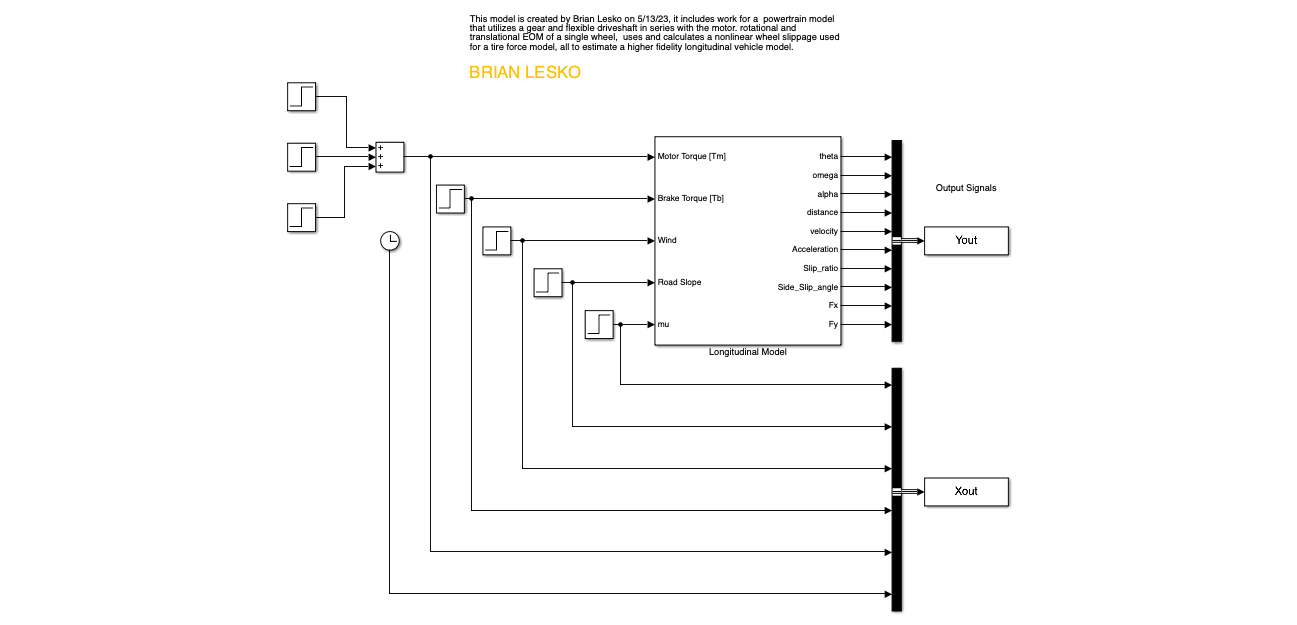

`The step signals are added to create the desired motor torque commands in the following situations where the velocity over time is taken to be the output of the simulation`

`Below, the simulation block, within the second level diagram is pictured.  It is split into 6 different components that each correlate back to an Equation of motion or a component equation. In the top left, a commented out box lays the groundwork for adding a flexible driveshaft at a later date. In the row below that, the nonlinear wheel slip equation exists. In the third row on the left, the drive torque on the wheel is calculated, and also has a commented out portion related to flexible driveshaft work. To the right of this is the rotational EOM of the wheel. In the last row on the left, the tire forces are calcaulted using the duggoff tire model. Lastly, the box in the bottom right is the translational EOM of the wheel. The minor pieces and parts outside these boxes are signals being sent to output. `

#### `Vehicle Model Diagram, separated by EOM`

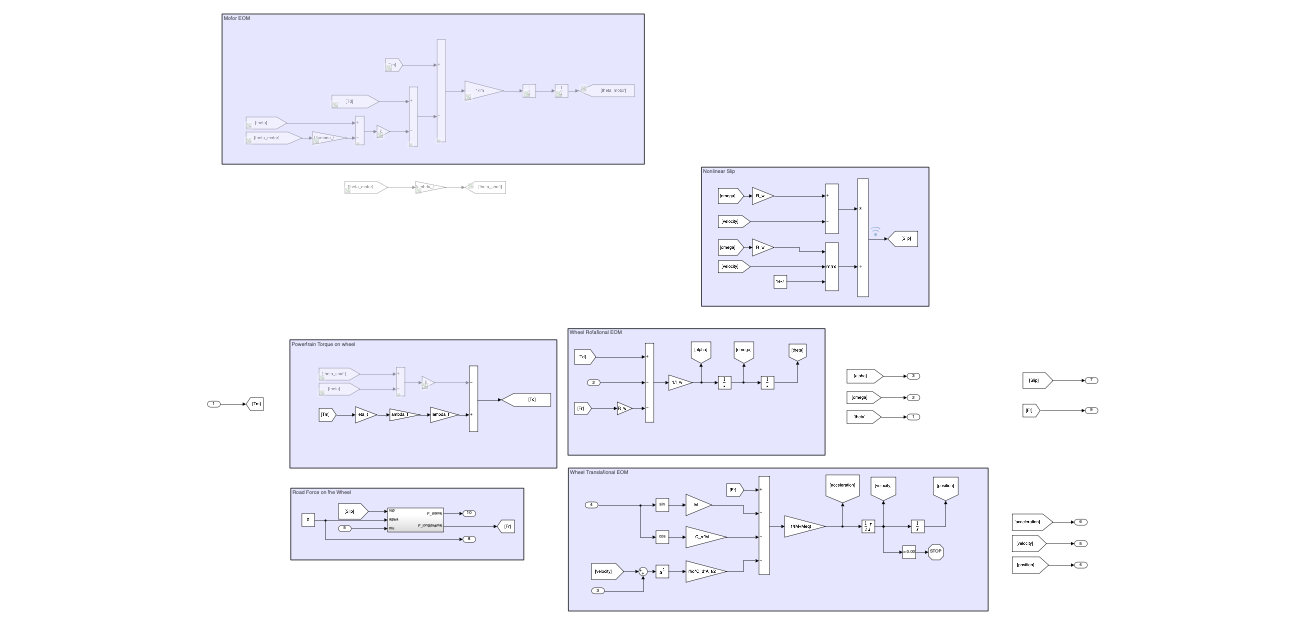

Brian Lesko

Powertrain torque on wheel, Componenet equation

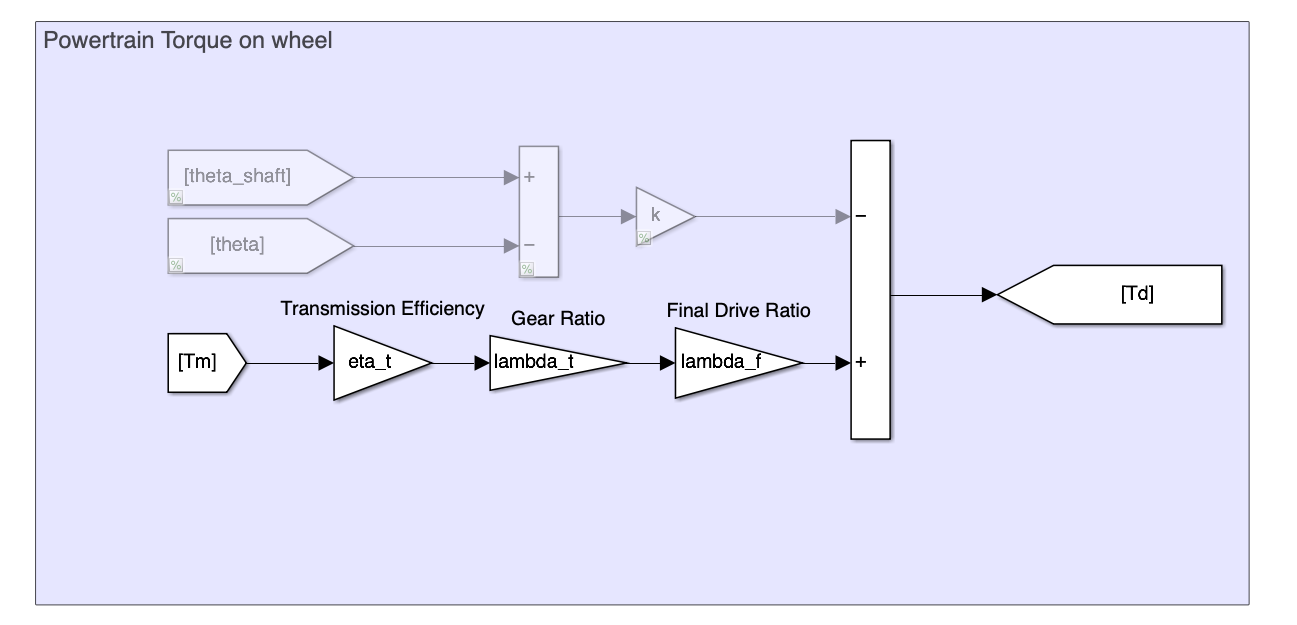

This portion of the EOM has been adapted to fit given empiracle data

Road Force on Wheel, Componenet equation

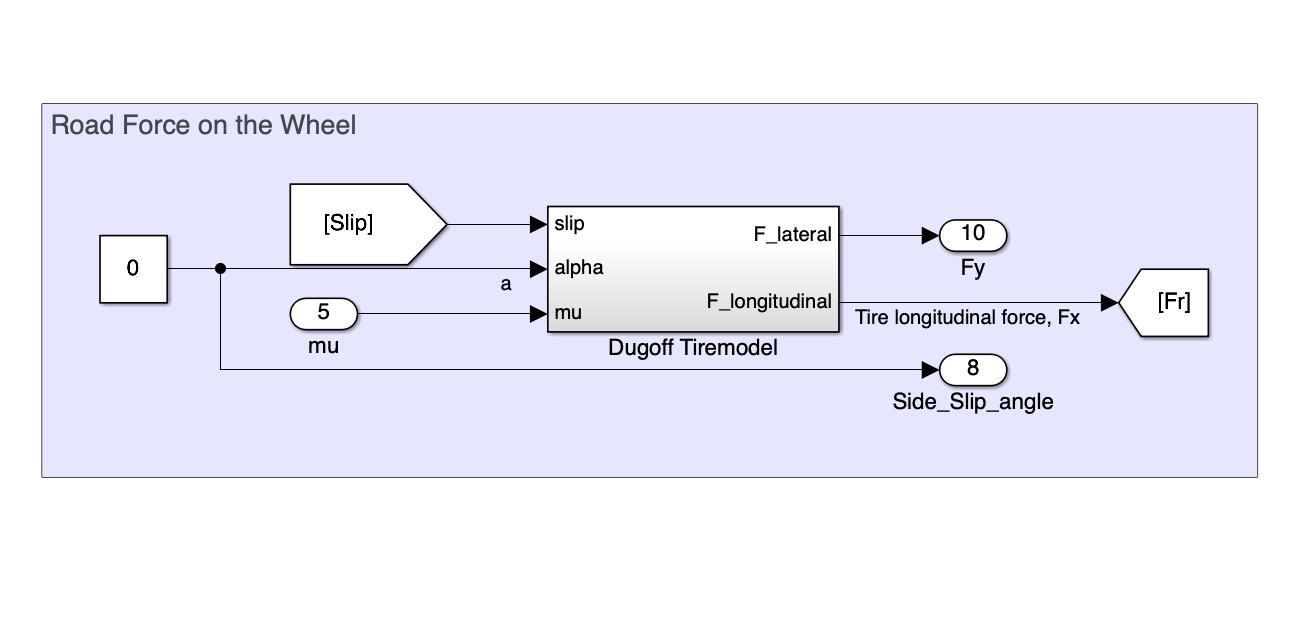

Wheel Slip, Componenet equation

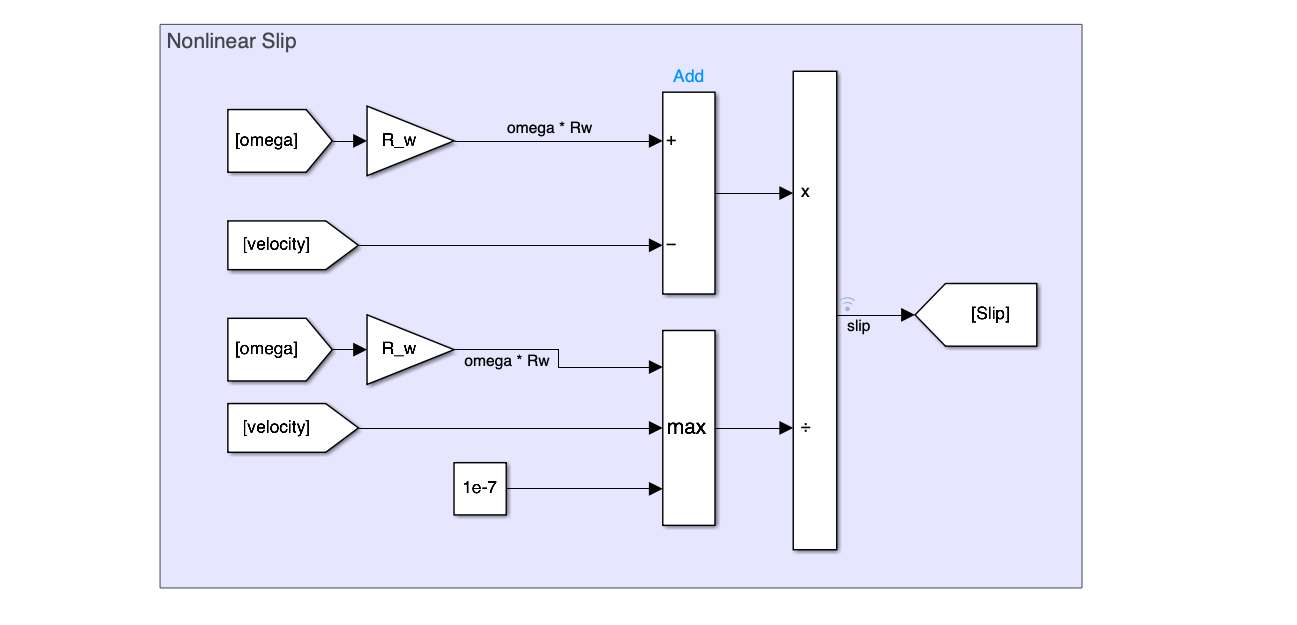

Wheel Rotational Equation of Motion

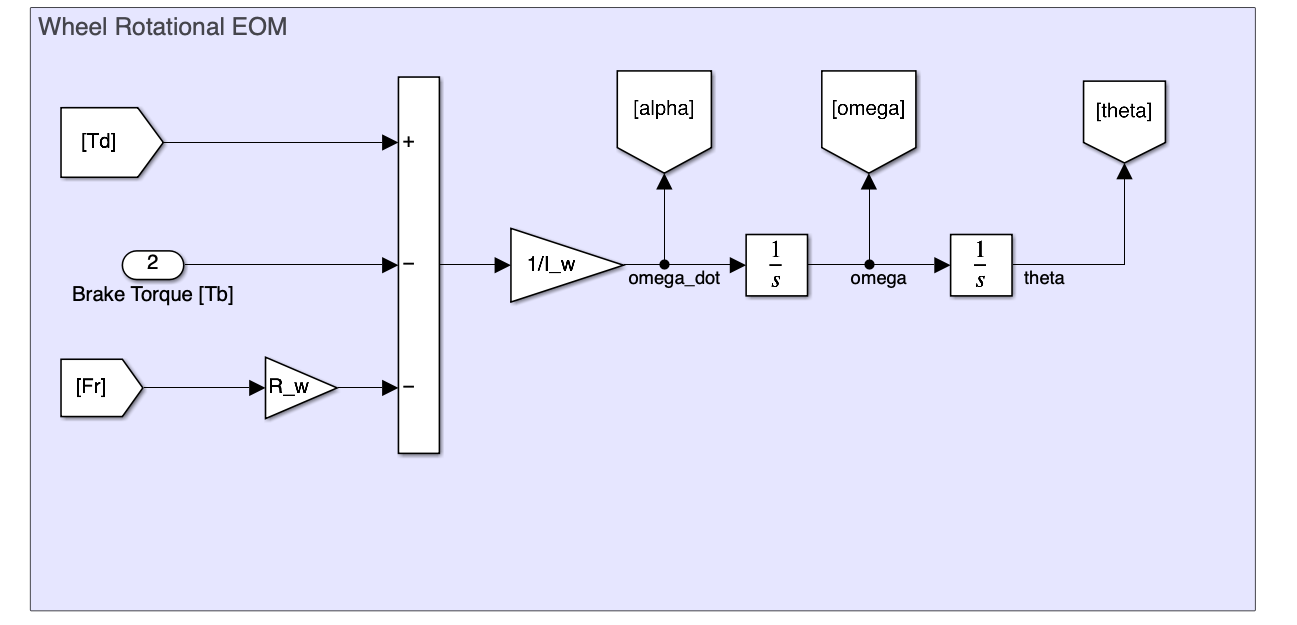

Wheel Translational Equation of Motion

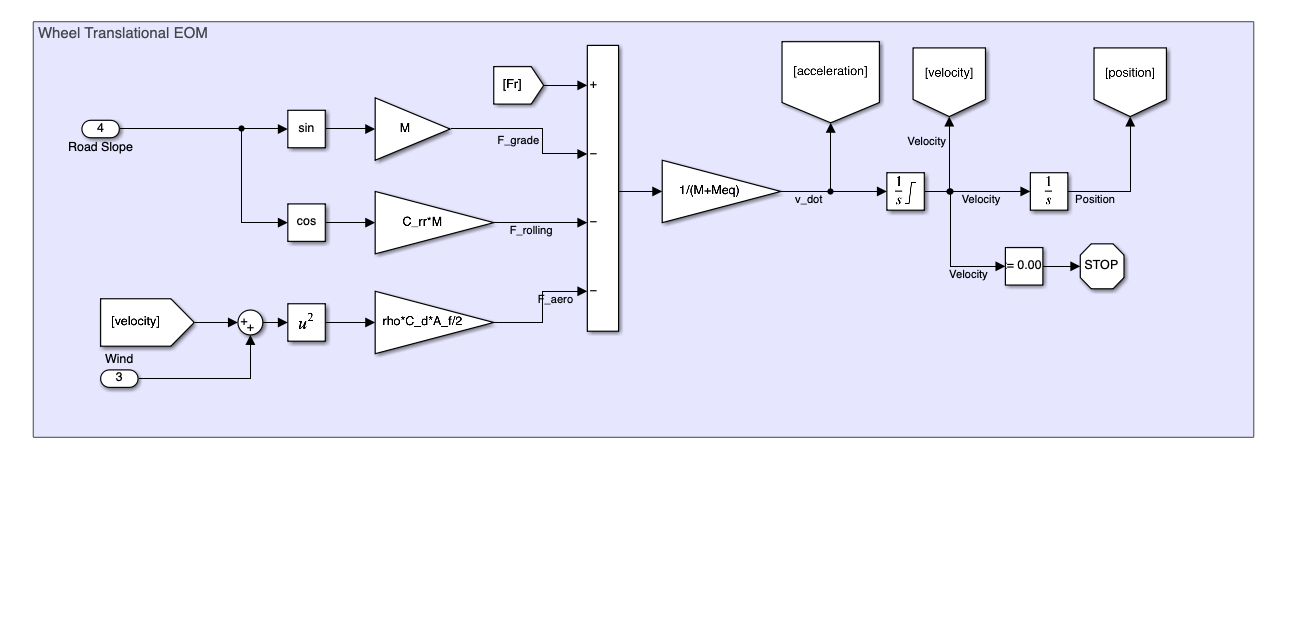

`Each section of the simulink corresponds to a different part of the Equations of motion `

clc; clear; close all;

# `Simulations `

## `LTI System Approximation `

`This first simulation of an acceleration exists to show that the complex EOM can be simplified with an approximate LTI system. However, this approach requires that many LTI systems be used to approximate more than one area of operation, as the LTI system needs to change for different motor torques, frictions, and other. It does relatively keep the same shape however. These approaches have been successfully implemented by others. `

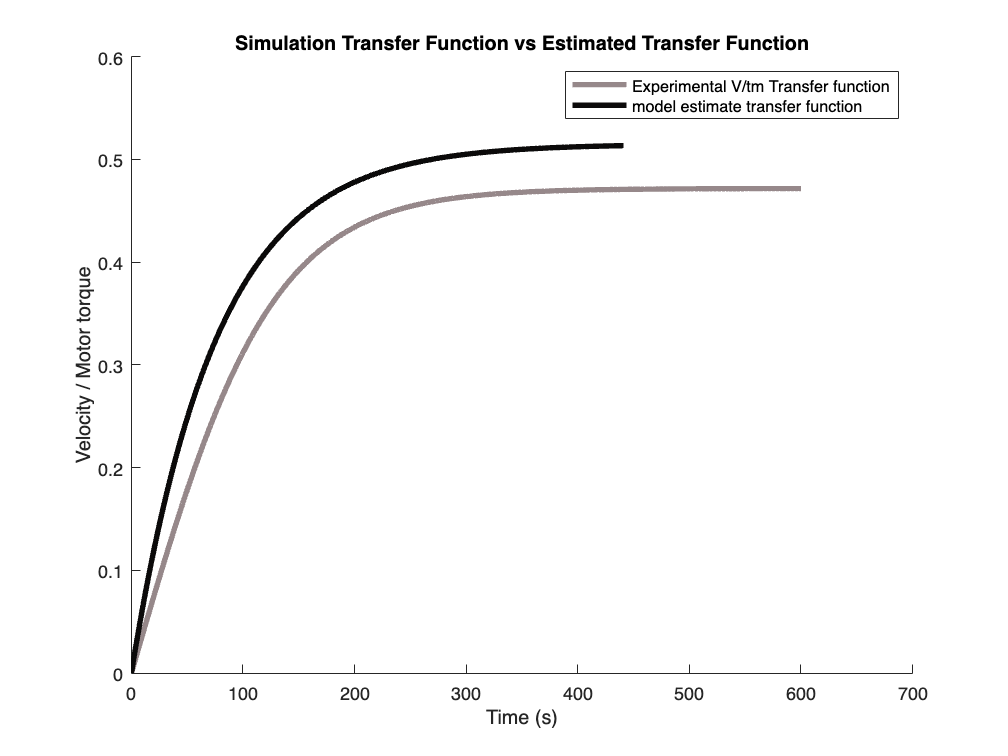

[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
motorStart = 75;
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('long_model')
ynames = ["Theta","Omega","Alpha","X","V","A","Slip Ratio","Slip angle","Fx","Fy"];
xnames = ["mu","Road Slope","Wind Force","Brake Torque","Motor Torque","Time"];

% Saving Simulation data
sim1y = Yout;
sim1x = Xout;
time1 = sim1x(:,length(xnames));

figure, hold on 
black = '#0B0A0A';
grey1 = '#484041' ;
grey = '#96888A';

% The simulated data
V = sim1y(:,5);
Tm = sim1x(:,5);
plot(time1,V./Tm,'Color',grey,'linewidth',3)

% Manual Approximation of an LTI system
K = 0.515;
T = 76;  
s = tf('s');
V_tf = K/ (T*s + 1);
[h,g] = step(V_tf);
plot(g, squeeze(h), 'Color', black,'LineWidth',3)

axis([0,700,0,.6])

legend('Experimental V/tm Transfer function','model estimate transfer function')
title('Simulation Transfer Function vs Estimated Transfer Function')
ylabel('Velocity / Motor torque'), xlabel('Time (s)')

`The LTI system is in the form Transfer function = K/ (T*s + 1) in the laplace domain. `

`The simulated velocity curve can be matched well by manually fitting the model coefficients. However, this is for specific road conditions and specific vehicle commands, how much can this velocity profile vary?`

# Acceleration Simulations

### Running and recording simulation data

In this simulation set, the vehicle accelerates until it reaches a steady state. 20 simulations each using a different constant motor torque. No wind or road slope. 

% unchanging Sim parameters for pure acceleration
[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

n=20;
for i = 1:1:n
    
    step = 10;
    motorStart = i*step + 40;

    % Create a Sim Name
    ID = ['pureAcceleration_', num2str(i)]; % this is a cell, which contains text
    sim('long_model')
    simResult = shortenAndTableSimVariables(Xout,Yout,ID); % save sim results as a table

    % We use cells to create n new tables
    vehicleCellsAcceleration{i} = simResult;
    varDescriptions = {'vehicle ID','time (s)', 'motor torque (Nm)', 'brake torque (Nm)','position (m)','velocity (m/s)','acceleration (m/s^2)','headwind (N)','road slope (deg)','friction coefficient'};
    vehicleCellsAcceleration{i}.Properties.VariableDescriptions = varDescriptions;
end
accelerationSims = vertcat(vehicleCellsAcceleration{:,1},vehicleCellsAcceleration{:,2},vehicleCellsAcceleration{:,3},vehicleCellsAcceleration{:,4})

accelerationSims = 2400×10 table
          IDvec              time       Tm    Tb        X            V            A         wind    slope    mu 
    __________________    __________    __    __    __________    ________    __________    ____    _____    ___

    pureAcceleration_1             0    50    0              0        0.01        3.2846     0        0      0.7
    pureAcceleration_1    0.00096324    50    0     1.0842e-05    0.011765      -0.10895     0        0      0.7
    pureAcceleration_1     0.0010892    50    0     1.2325e-05    0.011787      -0.10909     0        0      0.7
    pureAcceleration_1      0.001194    50    0     1.3561e-0

writetable(accelerationSims, 'accelerationSims.csv', 'Delimiter', ',', 'QuoteStrings', true);

## Plotting

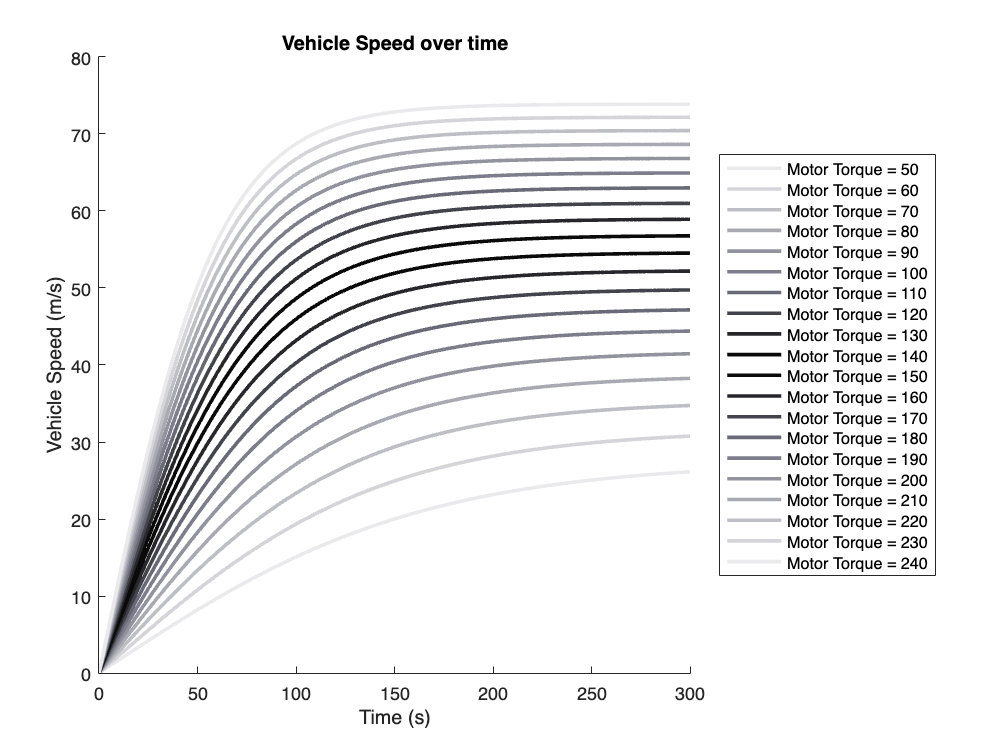

close all, figure, hold on, colors = getColors();
plotSimCellsV_t(vehicleCellsAcceleration)
title('Vehicle Speed over time'), xlabel('Time (s)'), ylabel('Vehicle Speed (m/s)'),legend(legendInfo, 'Location', 'eastoutside')
xlim([0 300])

# Coast Down Simulations

In this simulation scenario, the vehicle accelerates for a time until the motor torque is then set to zero and the vehicle coasts until coming to a stop. The dominant factor here is the rolling resistance, which can be tuned in future work. For this project, the coast down times have been tuned arbitrarily to let the sedan type vehicle coast for multiple minutes after gaining more than highway speeds 80+ mph. 

[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

motorDecreaseTime = 100;

n=20;
for i = 1:1:n
    step = 5;
    motorStart = i*step+25;
    motorDecrease = motorStart;
    % Create a Sim Name
    ID = ['CoastDown_', num2str(i)]; % this is a cell, which contains text
    sim('long_model')

    % Xout and Yout index beyond t=motorDecreaseTime
    a = find(Xout(:,6)>motorDecreaseTime);

    simResult = shortenAndTableSimVariables(Xout(a,:),Yout(a,:),ID);
    vehicleCellsCoast{i} = simResult;
    varDescriptions = {'vehicle ID','time (s)', 'motor torque (Nm)', 'brake torque (Nm)','position (m)','velocity (m/s)','acceleration (m/s^2)','headwind (N)','road slope (deg)','friction coefficient'};
    vehicleCellsCoast{i}.Properties.VariableDescriptions = varDescriptions;
end
coastSims = vertcat(vehicleCellsCoast{:,1})

coastSims = 151×10 table
       IDvec        time     Tm    Tb      X         V           A         wind    slope    mu 
    ___________    ______    __    __    ______    ______    __________    ____    _____    ___

    CoastDown_1       100    0     0     286.51    5.5992      0.058717     0        0      0.7
    CoastDown_1    102.95    0     0     302.53    5.2597     -0.052766     0        0      0.7
    CoastDown_1    105.72    0     0     316.67    4.9429       -0.1004     0        0      0.7
    CoastDown_1    108.33    0     0     329.16    4.6466     -0.063152     0        0      0.7
    CoastDown_1    110.78    0     0     340.21    4.3697 

writetable(coastSims, 'coastSims.csv', 'Delimiter', ',', 'QuoteStrings', true);

One method to improve these results is to bake initial conditions into the simulink model, so that the acceleration period need not be simulated

## Plotting Coast Down

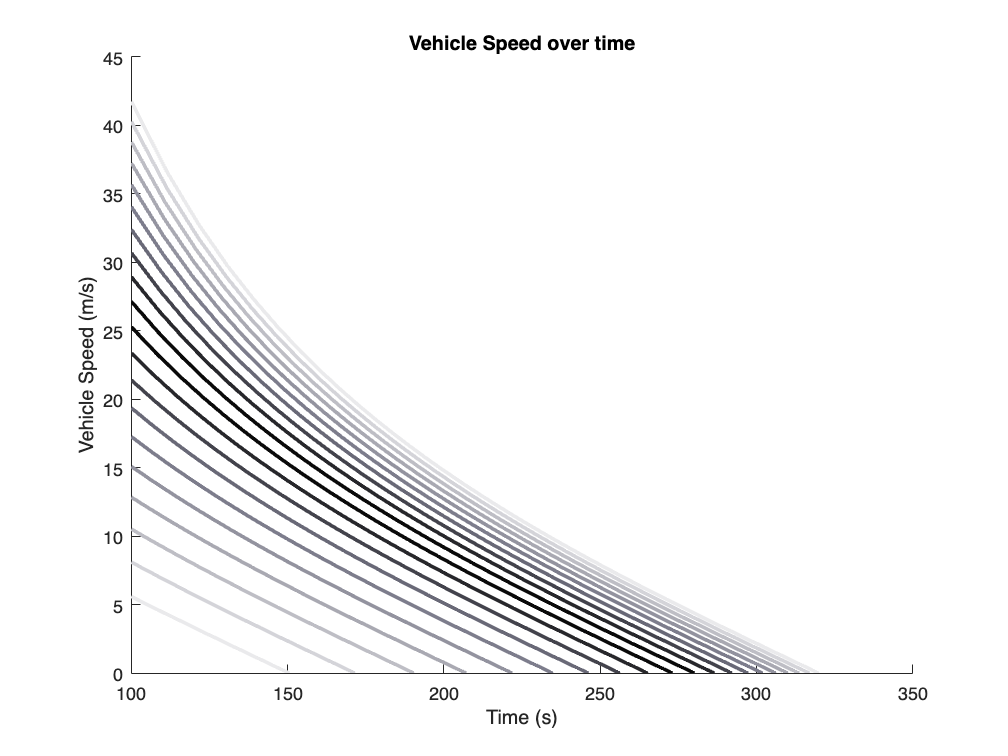

close all, figure, hold on 
plotSimCellsV_t(vehicleCellsCoast)
title('Vehicle Speed over time'), xlabel('Time (s)'), ylabel('Vehicle Speed (m/s)')

## Coast Down Approximation

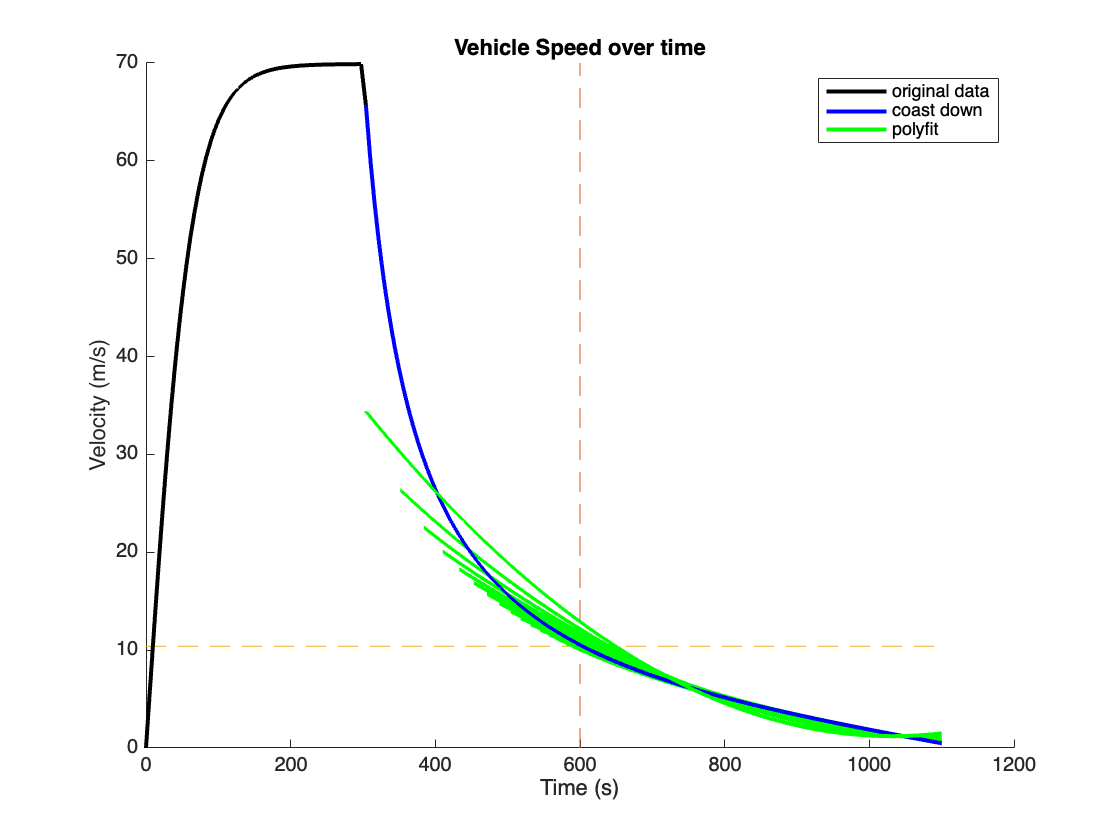

figure
hold on
extractFrom = 120;
for extractFrom = 800:-10:120
    len = length(time);
    extractTo = len;
    plta = plot(time,V,'k','linewidth',2);
    pltb = plot(time(extractFrom:extractTo),V(extractFrom:extractTo),'b','linewidt',2);
    p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
    x = time(extractFrom:extractTo);
    poly = p(1)*x.^2 + p(2)*x + p(3);
    pltc = plot(x,poly,'g','linewidth',2);
    if extractFrom == 270
        x = [600 600 600]; h = [0 100 1100];
        y = [0 50 70]; g = [10.4 10.4 10.4];
        plot(x,y,'--')
        plot(h,g,'--')
    end 
    drawnow
end 
legend('original data','coast down','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

A second order polynomial approximates the coast down velocity profile well for speeds below 10 m/s. Basis functions could be created to extend to higher speeds. This would require organizing many LTI systems for lookup during a control scheme. This has been done before. 

# Brake Simulations

Let Speed settle with a given Tm, then record the braking response

[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

motorDecreaseTime = 100;
brakeTime = 100;
breakStrength = 100; % this is spelled wrong

n=20;
for i = 1:1:n
    step = 5;
    motorStart = i*step+25;
    motorDecrease = motorStart;
    % Create a Sim Name
    ID = ['FullBrake_', num2str(i)]; % this is a cell, which contains text
    sim('long_model')
    % Xout and Yout index beyond t=motorDecreaseTime
    a = find(Xout(:,6)>motorDecreaseTime);
    simResult = shortenAndTableSimVariables(Xout(a,:),Yout(a,:),ID);
    vehicleCellsBrake{i} = simResult;
    varDescriptions = {'vehicle ID','time (s)', 'motor torque (Nm)', 'brake torque (Nm)','position (m)','velocity (m/s)','acceleration (m/s^2)','headwind (N)','road slope (deg)','friction coefficient'};
    vehicleCellsBrake{i}.Properties.VariableDescriptions = varDescriptions;
end
brakeSims = vertcat(vehicleCellsBrake{:,1})

brakeSims = 121×10 table
       IDvec        time     Tm    Tb       X         V          A        wind    slope    mu 
    ___________    ______    __    ___    ______    ______    ________    ____    _____    ___

    FullBrake_1       100    0     100    286.51    5.5992    0.058717     0        0      0.7
    FullBrake_1    101.31    0     100    293.62    5.2514    -0.22179     0        0      0.7
    FullBrake_1    102.54    0     100    299.89    4.9246    -0.20737     0        0      0.7
    FullBrake_1     103.7    0     100    305.41     4.619    -0.21567     0        0      0.7
    FullBrake_1    104.78    0     100    310.26     4.333    -0

writetable(brakeSims, 'brakeSims.csv', 'Delimiter', ',', 'QuoteStrings', true);

## Plotting Brake Response

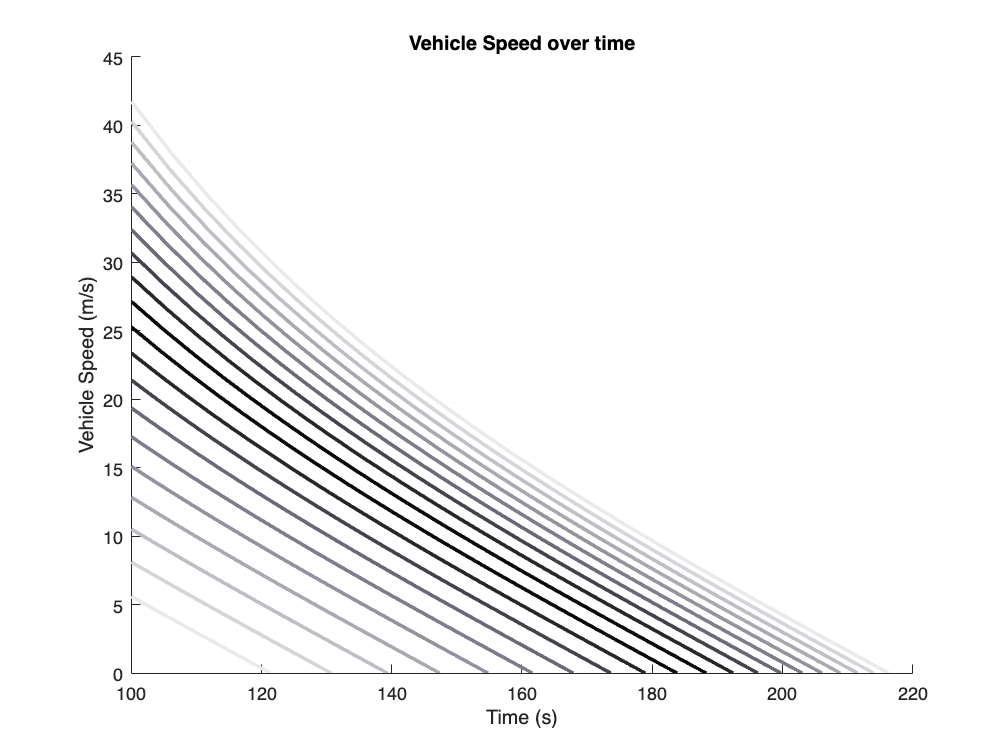

colors = getColors();
figure, hold on 

for i = 1:1:n
    % fetching the variables 
    time = vehicleCellsBrake{i}.time;
    V = vehicleCellsBrake{i}.V;
    Tm = vehicleCellsBrake{i}.Tm(1); % (1) because the motor torque is constant
    color = colors(i);
    plot(time,V,'r','linewidth',2,'Color',color);
    legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));

end 

title('Vehicle Speed over time'), xlabel('Time (s)'), ylabel('Vehicle Speed (m/s)')

# More Brake Simulations

Now lets test some other brake Torques. This is 400 Simulations so it will take a while 

[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

motorDecreaseTime = 100;
brakeTime = 100;

m = 20; 
loop = 1; 
for j = 1:1:m 
    breakStrength = 50+j*10;
    n=20;
    for i = 1:1:n
        step = 8;
        motorStart = i*step+25;
        motorDecrease = motorStart;
        % Create a Sim Name
        ID = ['FullBrake_', num2str(i)]; % this is a cell, which contains text
        sim('long_model')
        % Xout and Yout index beyond t=motorDecreaseTime
        a = find(Xout(:,6)>motorDecreaseTime);
        simResult = shortenAndTableSimVariables(Xout(a,:),Yout(a,:),ID);
        vehicleCellsBrake2{loop} = simResult;
        varDescriptions = {'vehicle ID','time (s)', 'motor torque (Nm)', 'brake torque (Nm)','position (m)','velocity (m/s)','acceleration (m/s^2)','headwind (N)','road slope (deg)','friction coefficient'};
        vehicleCellsBrake2{loop}.Properties.VariableDescriptions = varDescriptions;
        loop = loop + 1;
    end
end

# Simulation Summary 

The simulation data collected thus far can be refined and simplified. One way a coast or brake simulation profile can be summarised is with an average acceleration, its start state, end state, the wheel torques, and the duration of time. 

Average acceleration can be calculated with Vend - Vstart / duration of time

## Summarization

20 acceleration sims 

[avg_acc,dtime,Xs,Xe,Vs,Ve,As,Ae,Tm,Tb] = getSummaryStateVars(vehicleCellsAcceleration);
names = {'Xs','Vs','As','Xe','Ve','Ae','avg_acc','time','Tm','Tb'};
accSimsSummary = table(Xs',Vs',As',Xe',Ve',Ae',avg_acc',dtime',Tm',Tb', 'VariableNames', names);
writetable(accSimsSummary, 'accelerationSimsSummary.csv', 'Delimiter', ',', 'QuoteStrings', true);

20 coast down sims

[avg_acc,dtime,Xs,Xe,Vs,Ve,As,Ae,Tm,Tb] = getSummaryStateVars(vehicleCellsCoast);
names = {'Xs','Vs','As','Xe','Ve','Ae','avg_acc','time','Tm','Tb'};
coastSimsSummary = table(Xs',Vs',As',Xe',Ve',Ae',avg_acc',dtime',Tm',Tb', 'VariableNames', names);
writetable(coastSimsSummary, 'coastSimsSummary.csv', 'Delimiter', ',', 'QuoteStrings', true);

400 brake sims 

[avg_acc,dtime,Xs,Xe,Vs,Ve,As,Ae,Tm,Tb] = getSummaryStateVars(vehicleCellsBrake2);
names = {'Xs','Vs','As','Xe','Ve','Ae','avg_acc','time','Tm','Tb'};
brakeSimsSummary = table(Xs',Vs',As',Xe',Ve',Ae',avg_acc',dtime',Tm',Tb', 'VariableNames', names);
writetable(brakeSimsSummary, 'brakeSimsSummary.csv', 'Delimiter', ',', 'QuoteStrings', true);

To visualize the average acceleration 

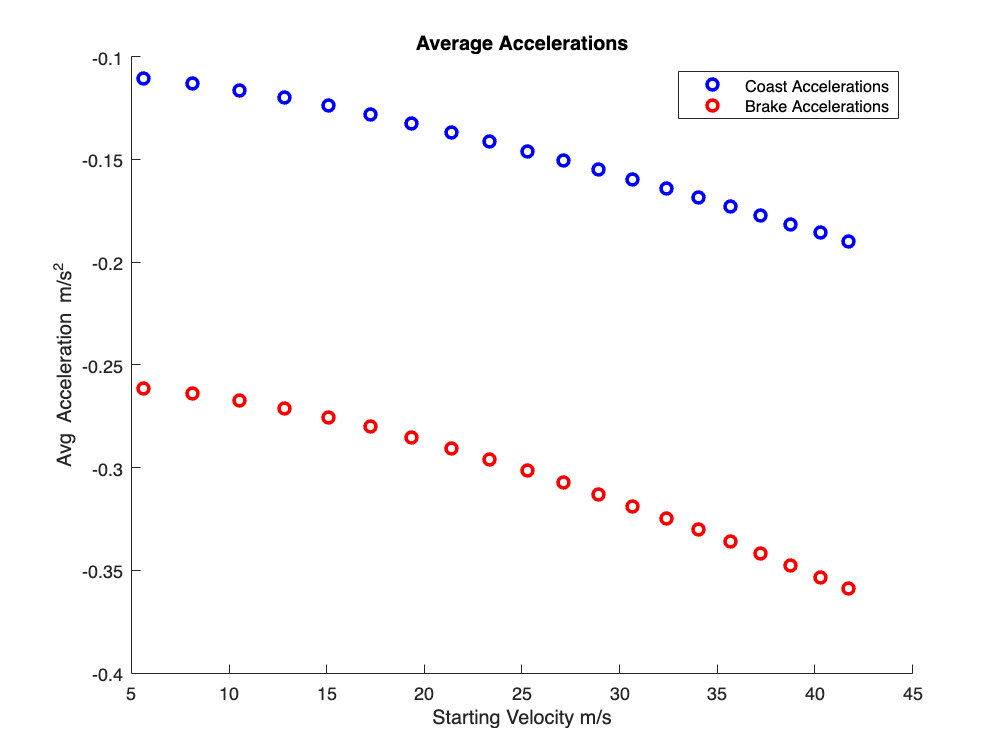

%Here is a visual demonstration that represents each of the original 20 coast down and 20 brake simulations with one data point each.

% lets get the average accelerations for each of the sim sets
[avg_accsCoast,startVelCoast,endVelStart] = getAvgAccAndVel(vehicleCellsCoast);
[avg_accsBrake,startVelBrake,endVelBrake] = getAvgAccAndVel(vehicleCellsBrake);

figure, hold on
plot(startVelCoast,avg_accsCoast,'o','Color','b','LineWidth',2)
plot(startVelBrake,avg_accsBrake,'o','Color','r','LineWidth',2)
legend('Coast Accelerations','Brake Accelerations')
ylabel('Avg Acceleration m/s^2'),xlabel('Starting Velocity m/s')
title('Average Accelerations')

Each of these data points represents one of the original 40 simulations between coasting and braking. This data is part of the summary data compiled into CSV

# Targeting a Vehicle State, for stopping a vehicle

So far, the end state of the vehicle has been a product of the set conditions, but what if we want to control the vehicle to achieve an end state? 

One method to control a vehicle to get from a start state to an end state is to control the acceleration. But what acceleration should be picked to achieve this? I hypothesize our solution should be robust to some wind and road slope, so for the time being lets ignore these characteristics. 

## Derivation of goal acceleration to acheive a vehicle state

Goal vehicle state : [X,V,A]end

Start vehicle state : [X,V,A]start

[X,V,A]end - [X,V,A]start = [X,V,A]change

A_needed = Vc / Time  (m/s^2)

Time = Xc / Avg_V (s) 

Avg_V = Vstart + Vchange/2  (m/s) 

Resulting in: A_needed = Vc (Vs + Vc/2) / Xc (m/s^2)

Sanity Check: 

startState = [100,10,0];
endState = [0,0,0];
stateChange = endState - startState; 

Xc = stateChange(1);
Vc = stateChange(2);
Ac = stateChange(3);

avg_V = startState(2) + Vc/2 % average velocity 

avg_V = 5

time = abs(Xc / avg_V) % total time to travel

time = 20

Ademanded = Vc / time % demanded acceleration 

Ademanded = -0.5000

Now that a goal acceleration is picked, how does the vehicle achieve this? Coasting or braking? A complexity is that braking is a continuous range of net wheel torques that are negative, and coasting is the special case of net torque = 0. 

Framing the problem this way, our new problem is a regression problem with motor torque as the target, given current and end vehicle state.

coast Tm - Tb = 0 or brake Tm - Tb < 0

We now have everything from the simulations to formulate labeled data. This is hypothesized to be useful for solving the regression problem. 

This regression problem is defined with 8 predictors and 1 target (Tm-Tb)

brakeSimsSummary

brakeSimsSummary = 400×10 table
      Xs        Vs         As         Xe       Ve         Ae       avg_acc      time     Tm    Tb
    ______    ______    ________    ______    _____    ________    ________    ______    __    __

         0         0           0         0        0           0           0         0    0      0
    573.45     10.99    0.048089    858.08    0.001     -1.7439    -0.20764    52.925    0     60
    774.88    14.647     0.11627    1257.8    0.001     -1.7673    -0.21404    68.426    0     60
    970.67    18.108     0.19279    1671.9    0.001     -2.8903    -0.22142    81.776    0     60
    1161.2    21.391     0.14794    208

# Functions

function [M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters()
    M=2000; % Mass of the vehicle[Kg]
    eta_t=0.9; % Transmission Efficiency
    lambda_t=1.0; % Gear Ratio
    lambda_f=4.1; % Final Drive Ratio
    I_w=1.1; % Inertia of the Wheel[kgm2]
    R_w=0.3; % Wheel Radius[m]
    Meq=0.1*M; % Equivalent Mass Factor
    C_d=0.29; % Drag coefficient
    rho=1.225; % Air density[kg/m3]
    A_f=2.8;% Frontal area	[m2]
    g=9.81;% [N/m2]
    C_rr=0.12;%Rolling resistance coefficient Originally .015
    C_x=3e5; %Longitudinal Stiffness[N]
    C_alpha = 1.5e5; % Cornering Stiffness for 1 tire [N/rad]
    L=2.85;% Wheelbase[m]
    l_f=1.3;% Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    l_r=1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    C_s=1.5e5;% Cornering Stiffness of Front and Rear Tires [N/rad]
    I_z=3700;% Inertia moment around z axis J or Iz [kg/m2]
    mu=0.7; % Road friction coefficient
end 

function [motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero()  
    motorStart = 0; motorStartTime = 0;
    motorIncrease = 0;motorIncreaseTime = 0; 
    motorDecrease = 0;motorDecreaseTime = 0;
    brakeTime = 0;breakStrength = 0;
    headWindTime = 0;headWind = 0;
    roadSlopeTime = 0;roadSlope = 0;
end 


function y = sampVec(x, b)
    % x: input vector
    % b: length of output vector
    
    a = length(x);
    y = linspace(1, a, b)';
    y = round(y);
    y = x(y);
end

function [mu,slope,wind,Tb,Tm,time,theta,omega,alpha,X,V,A,slip,slipAngle,Fx,Fy] = importSimVariables(Xout,Yout)
    
    % Xout
    mu = Xout(:,1); % Road Coefficient of Friction 
    slope = Xout(:,2); % Road slope
    wind = Xout(:,3); %wind force 
    Tb = Xout(:,4); %Brake Torque
    Tm = Xout(:,5); % Motor Torque
    time = Xout(:,6); % time (s)

    %Yout
    theta = Yout(:,1);
    omega = Yout(:,2);
    alpha = Yout(:,3);
    X = Yout(:,4);
    V = Yout(:,5);
    A = Yout(:,6);
    slip = Yout(:,7);
    slipAngle = Yout(:,8);
    Fx = Yout(:,9);
    Fy = Yout(:,10);

end 

function simResult = shortenAndTableSimVariables(Xout,Yout,ID)

    [mu,slope,wind,Tb,Tm,time,theta,omega,alpha,X,V,A,slip,slipAngle,Fx,Fy] = importSimVariables(Xout,Yout);

    b = length(time);

    % reduce samples to length b
    b = round(max(time)*1); % samples per second of sim time

    names = {'IDvec','time','Tm','Tb','X','V','A','wind','slope','mu'};

    time = sampVec(time, b); Tm = sampVec(Tm, b); Tb = sampVec(Tb, b); X = sampVec(X, b); V = sampVec(V, b); A = sampVec(A, b);
    wind = sampVec(wind, b); mu = sampVec(mu, b); slope = sampVec(slope, b);

    IDvec = repmat(ID, b , 1);
    simResult = table(IDvec,time,Tm,Tb,X,V,A,wind,slope,mu, 'VariableNames', names);
end 

function plotSimCellsV_t(simCells)
n = length(simCells(1,:));
colors = getColors();
    for i = 1:1:n
        % fetching the variables 
        time = simCells{i}.time;
        V = simCells{i}.V;
        Tm = simCells{i}.Tm(1); % (1) because the motor torque is constant
        color = colors(i);
        plot(time,V,'r','linewidth',2,'Color',color);
        legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));
    end 
end 

function plotSimCellsA_t(simCells)
n = length(simCells(1,:));
colors = getColors();
    for i = 1:1:n
        % fetching the variables 
        time = simCells{i}.time;
        A = simCells{i}.A;
        Tm = simCells{i}.Tm(1); % (1) because the motor torque is constant
        color = colors(i);
        plot(time,A,'r','linewidth',2,'Color',color);
        legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));
    end 
end 

function [avg_accelerations,startVel,endVel] = getAvgAccAndVel(simCells)
n = length(simCells(1,:));
avg_accelerations = zeros(1,n);
    for i = 1:1:n
        % fetching the variables 
        delta_time = max(simCells{i}.time)-min(simCells{i}.time);
        startVel(i) = simCells{i}.V(1);
        endVel(i) = simCells{i}.V(length(simCells{i}.V));
        avg_accelerations(i) = (endVel(i)-startVel(i))/delta_time;
    end 
end 

function [avg_acc,dtime,Xs,Xe,Vs,Ve,As,Ae,Tm,Tb] = getSummaryStateVars(simCells)
n = length(simCells(1,:));
avg_acc=zeros(1,n); dtime=zeros(1,n); Xs=dtime; Xe=dtime; Vs=dtime; Ve=dtime; As=dtime; Ae=dtime; Tm = dtime; Tb = dtime; 
    for i = 2:1:n
        % fetching the variables 
        dtime(i) = max(simCells{i}.time)-min(simCells{i}.time);
        Vs(i) = simCells{i}.V(1); Ve(i) = simCells{i}.V(length(simCells{i}.V));
        avg_acc(i) = (Ve(i)-Vs(i))/dtime(i);

        Xs(i) = simCells{i}.X(1); Xe(i) = simCells{i}.X(length(simCells{i}.X));  
        As(i) = simCells{i}.A(1); Ae(i) = simCells{i}.A(length(simCells{i}.A));
        Tm(i) = simCells{i}.Tm(length(simCells{i}.Tm));
        Tb(i) = simCells{i}.Tb(1);
    end 
end 

function colors = getColors()
    a = "#0A0A0A"; % night
    %b = "#131315"; % night 
    %c = "#1D1D20"; % eerie black
    d = "#27272B"; % raisin black
    %e = "#303036"; % jet
    %f = "#3A3A41"; % onyx
    g = "#43434C"; % onyx
    %h = "#565661"; % davy"s gray
    %i = "#60606C"; % dim gray
    j = "#696977"; % dim gray
    %k = "#737382"; % slate gray
    l = "#7D7D8C"; % taupe gray
    m = "#93939F"; % cool gray
    n = "#A9A9B2"; % french gray
    o = "#BEBEC5"; % french gray
    p = "#D4D4D9"; % platinum
    q = "#EAEAEC"; % anti-flash white

    colors = [q,p,o,n,m,l,j,g,d,a,a,d,g,j,l,m,n,o,p,q]; 
end     